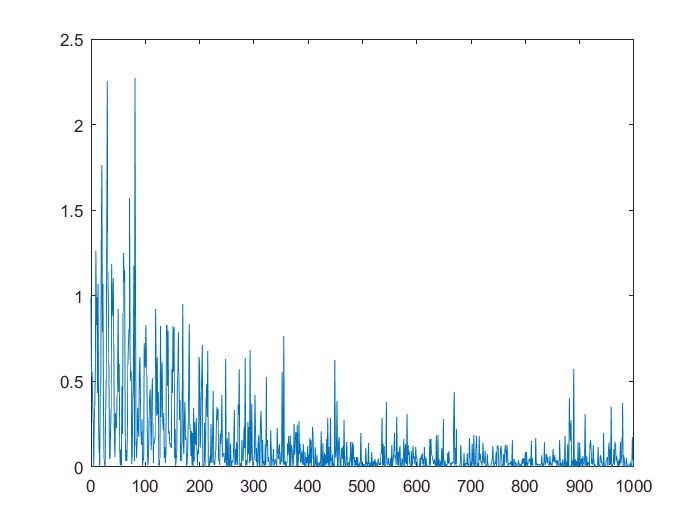

%************** ALE using LMS ****************
clc; clear all; close all;
N=1000; % no of simulation samples
M=64;% FIR filter length
SNR=10; % Sinusoid SNR in dB
mu=.01/64;% LMS step-size
n=0:N;
A=1;
fd0=1/20;%fd0=f0/fs
Nn=A*cos(2*pi*fd0*n);
x=Nn+sqrt(1/2/(10^(SNR/10)))*randn(1,N+1);%x=Nn+Bn

xd=filter([0 1],1,x);%delay x by one sample
y=zeros(1,N+1);%initialize y to zero
e=zeros(1,N+1);%initialize e to zero
w0=zeros(1,M);%initialize weight vector to zero
z=zeros(1,M-1);%initialize filter memory to zero
xdm=zeros(1,M);% for holding xd

for k=1:N+1
[y(k),z]=filter(w0,1,x(k),z);%filter one sample at a time
e(k)=x(k)-y(k);%error signal
w0=w0+2*mu*e(k)*xdm;%update the weight vetcor
 w0(i,n+1) = w0(i,n)+mu(i)*e(n)*x(n);
 w1(i,n+1) = w1(i,n)+mu(i)*e(n)*x(n-1);
xdm=[xd(k) xdm(1:M-1)];
end

[w0,F]=freqz(w0,1,512);
w0=20*log10(abs(w0));
figure;
plot(n,e.^2);

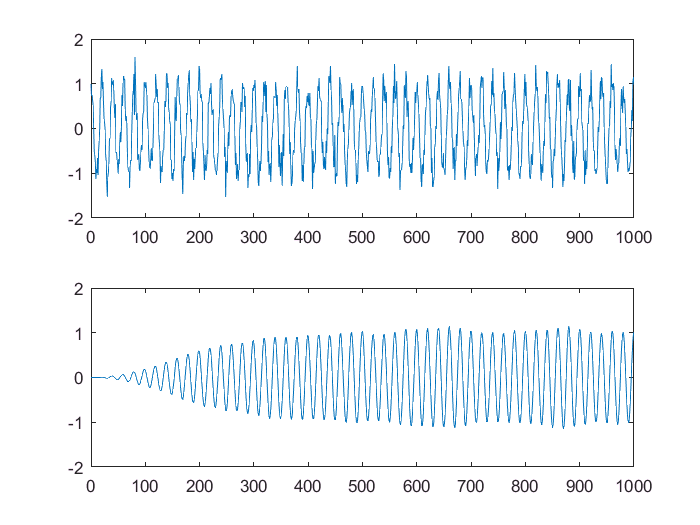

figure;
subplot(211);
plot(n,x);
subplot(212);
plot(n,y);

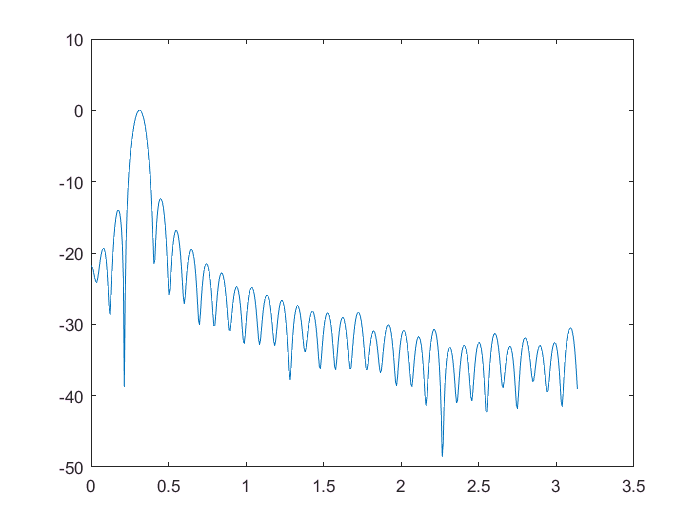

figure;
plot(F,w0);